# Test Exam F25

## Q1

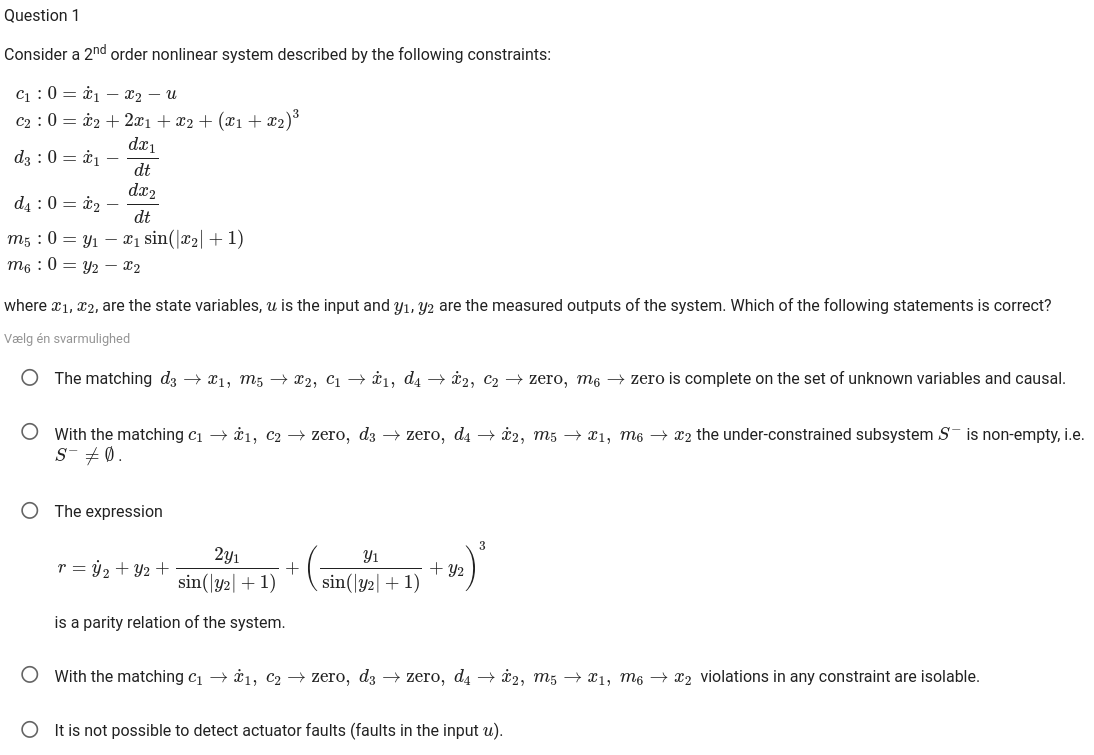

clc
clear all

% Inputs
syms u(t) % Symbolic input declaration
ST_input(1,:) = {u}; % symbolic variable
ST_input(2,:) = {'u\\left(t\\right)'}; % LaTeX expression


% Measurements
syms y1(t) y2(t) % Symbolic measurement declaration
ST_meas(1,:) = {y1, y2}; % symbolic variable
ST_meas(2,:) = {'y1\\left(t\\right)', 'y2\\left(t\\right)'}; % LaTeX expression

% Parameters
syms a % Symbolic parameters declaration
ST_parameters(1,:) = {a}; % symbolic variable
ST_parameters(2,:) = {'a'}; % LaTeX expression

% Unknowns
syms x1(t) x2(t) dx1(t) dx2(t) %Symbolic unknowns declaration
ST_unknowns(1,:) = {x1, x2, dx1, dx2}; % symbolic variable
ST_unknowns(2,:) = {'x1', 'x2', '\dot x_1', '\dot x_2'}; % LaTeX expression

% Enter the constraints of the system
% ST_cons(1.:) comprise the Matlab names of constraints
% ST_cons(2.:) comprise the Latex
% ST_cons(3,:) comprise a cell array list with the expressions of the constraints



ST_cons(1,:) = {'c1','c2','d3','d4','m5','m6'}; % Constraint names
ST_cons(2,:) = {'c_1','c_2','d_3', 'd_4', 'm_5', 'm_6'}; % Constraint latex names
ST_cons(3,:) = {...
                0 == dx1 - x2 - u,...
                0 == dx2 + 2*x1 + x2 + (x1 + x2)^3,...
                0 == dx1 - diff(dx1, t),...
                0 == dx2 - diff(dx2, t),...
                0 == y1 - x1*sin(abs(x2) + 1),...
                0 == y2 - x2};
% NOTE that "diff(.,t)" is used as the differential operator, D == d/dt.
ST_canfail  = []; % constraint d7-d12 cannot fail
ST_domains  = [1 1 1 1 1 1 1 1 1 1 1 1 1 1 1];


% Automatic incMatrix generation
cons_oneway = {[],[],[],[],[],[],{x1},{x2},[],[],[]};
ST_IncMat = sa_incidencematrix(ST_cons,...
    ST_input,ST_meas,...
    ST_unknowns,cons_oneway);

% disp(ST_IncMat)

ST_sys =...
    sa_create(ST_IncMat,ST_cons,...
    ST_input, ST_meas,ST_unknowns,...
    ST_domains, ST_canfail,...
    ST_parameters);

Error using sa_create (line 199)
Invalid dimension of domain vector.


sa_disp(ST_sys);
ST_sys=sa_match(ST_sys,'mso'); % alternatively 'rank'

disp('Obtained matching:');
sa_disp(ST_sys, 't')
disp('Parity relation symbolic form:')
sa_disp(ST_sys, 's')
disp('Parity relation analytic form:')
sa_disp(ST_sys, 'a')

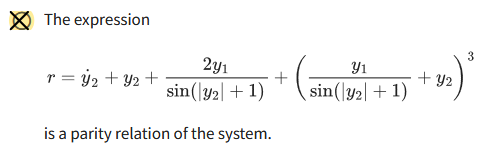

## Q2

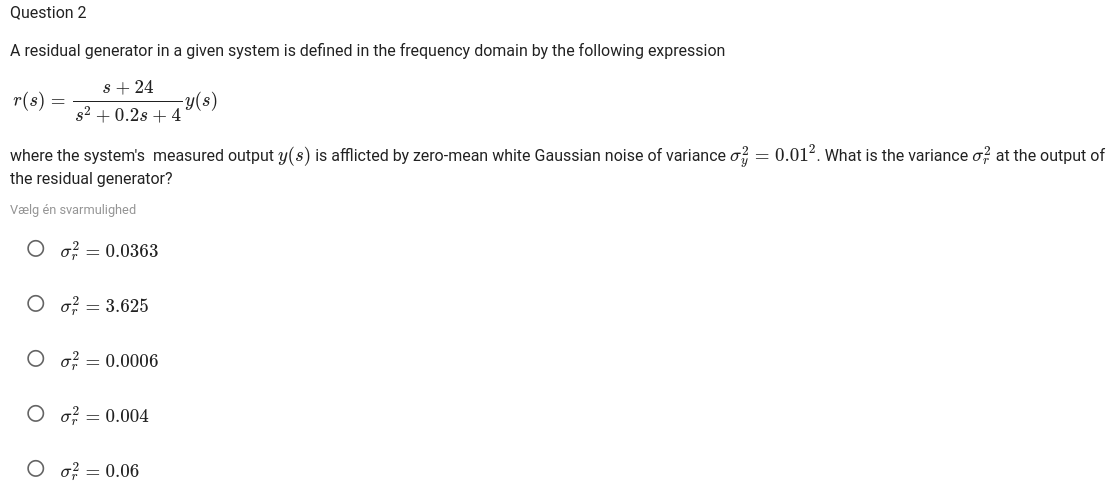

r = tf([1 24], [1 0.2 4]);
[A,B,C,D] = tf2ss([1 24], [1 0.2 4]);
sys = ss(A,B,C,D);

sigma_y= 0.01^2;
Qx = lyap(A, B * sigma_y * B');
Qy = C * Qx * C' + D * sigma_y * D'

Qy = 0.0363


$$Q_y =\sigma_r^2 =0\ldotp 0363$$


## Q3

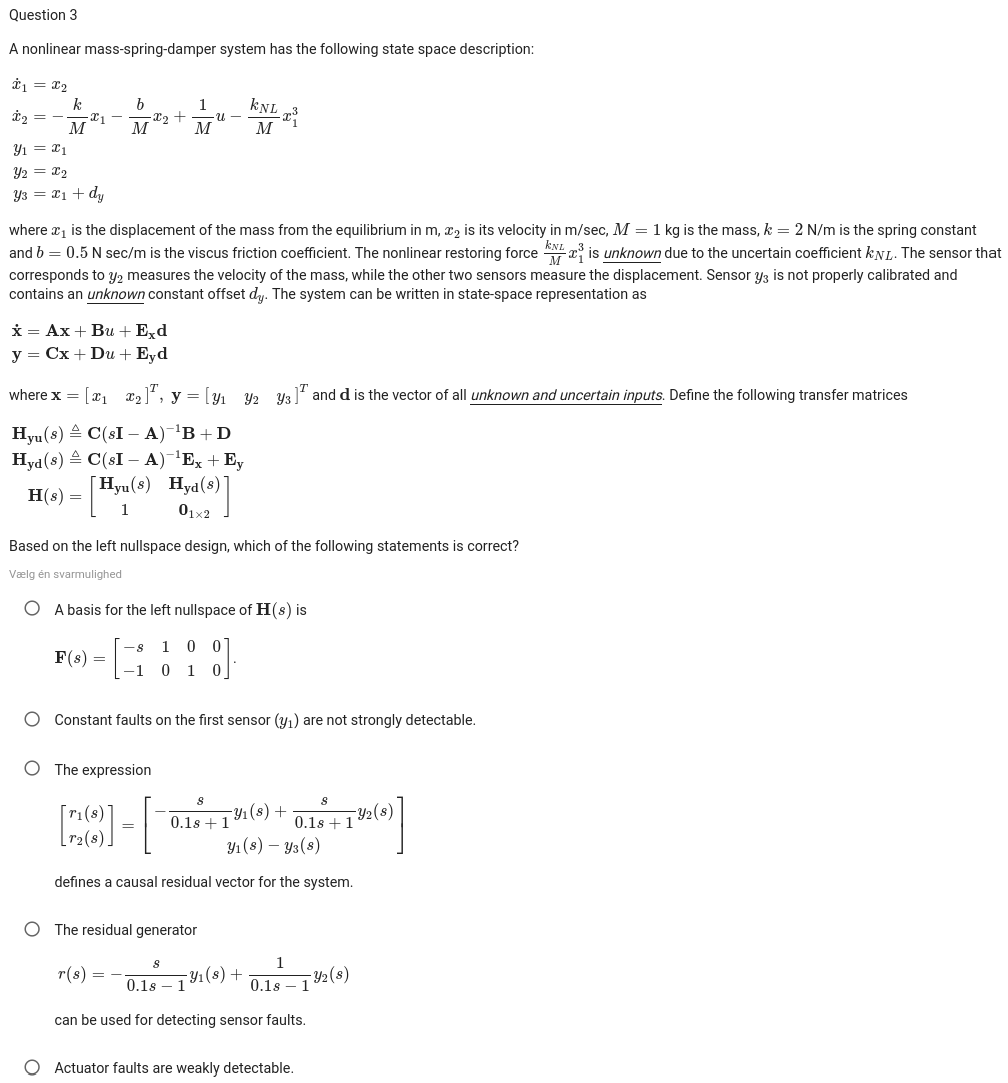

syms k_NL d_y s
M = 1;
k = 2;
b = 0.5;
A = [0 1
     -k/M -b/M];
B = [0; 1/M];
Ex = [1; 0];
C = [1, 0;
     0, 1;
     1, 0];
D = 0;
Ey = [0; 0; 1];
Fx = 0;
Fy = 0;
H_yu = C * inv(s*eye(size(A, 1)) - A) * B + D;
H_yd = C * inv(s*eye(size(A, 1)) - A) * Ex + Ey;
H_yf = C * inv(s*eye(size(A, 1)) - A) * Fx + Fy;
H = [H_yu, H_yd;
     eye(2, 1), zeros(2, 1)];
simplify(H);
F = simplify(null(H')')

$$F = \left(\begin{array}{ccccc} -s-1 & 1 & 1 & 0 & 0\\ -2 & -s-\frac{1}{2} & 0 & 1 & 0\\ 0 & 0 & 0 & 0 & 1 \end{array}\right)$$

$F\left(s\right)\not= \left\lbrack \begin{array}{cccc}
-s & 1 & 0 & 0\\
-1 & 0 & 1 & 0
\end{array}\right\rbrack$-> False

columns = {'y1', 'y2', 'y3', 'u'};
[num_rows, num_columns] = size(H_yf);

for i = 1:num_columns
    i_rank = rank([H_yd H_yf(:, i)]);
    disp(sprintf("Column #%d (%s)'s rank: %d", i, columns{i}, rank([H_yd H_yf(:, i)])));
    if i_rank > rank(H_yd)
        disp(sprintf("%s is weakly detectable", columns{i}))
    end
    strong_detectability = subs(F * [H_yf(:,i); zeros(2,1)], s, 0);
    for j = 1:length(strong_detectability)
        if strong_detectability(j) ~= 0
            disp(sprintf("Residual %d is strongly detectable", j));
        end
    end
    disp("-------------------------------------")
end

Column #1 (y1)'s rank: 1


-------------------------------------


Column #2 (y2)'s rank: 1


-------------------------------------


Actuator faults are not weakly detectable.

Replacing the first row of C with 0, doesn't make it strongly detectable.

V_ry = F(1:2, 1:3)

$$V\_ry = \left(\begin{array}{ccc} -s-1 & 1 & 1\\ -2 & -s-\frac{1}{2} & 0 \end{array}\right)$$

H_rf = V_ry * H_yf

$$H\_rf = \left(\begin{array}{cc} 0 & 0\\ 0 & 0 \end{array}\right)$$

## Q4

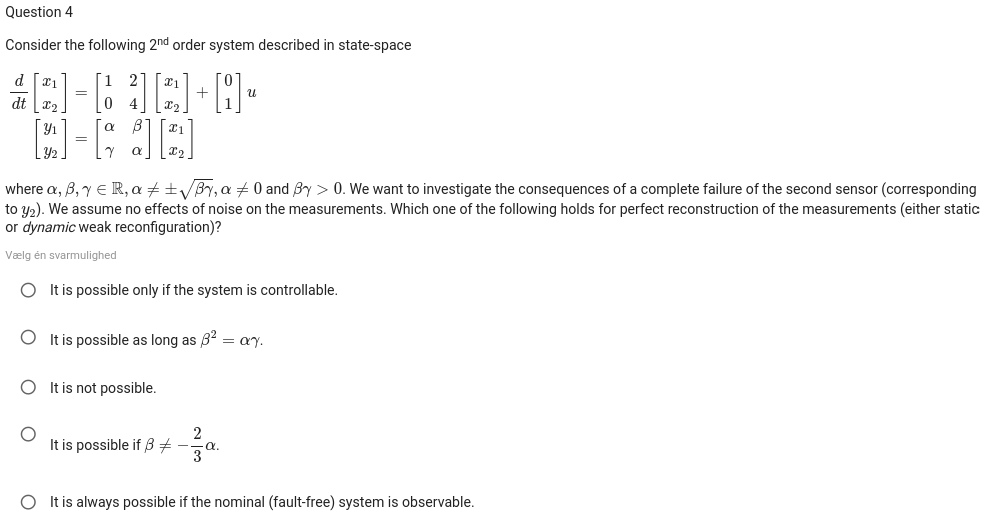

syms alpha beta gamma

assume(alpha ~= sqrt(beta*gamma))
assume(alpha ~= -sqrt(beta*gamma))
assume(alpha ~= 0)
assume(beta*gamma > 0)

assume(beta ~= -2*alpha/3)
% beta = sqrt(alpha*gamma);
alpha = 1;
beta = -2*alpha/3;

A = [1 2
     0 4];
B = [0; 1];
C = [alpha beta
     gamma alpha];

C_f = C(1, :);

Mc = ctrb(A,B);

% Test if the controlabillity matrix has at least as many
% linearly independant columns as the number of states in the system:
if rank(Mc) >= size(A,1)
	disp('System is controllable!');
else
	disp('System is NOT controllable!');
end

System is controllable!


% Static reconfiguration

if (rank(C_f) == rank([C; C_f])) % write the condition for perfect matching
    disp('Perfect matching for sensor fault');
else
    disp('Imperfect matching for sensor fault');
end

Imperfect matching for sensor fault


By analytical approach: option 2 and 4 is incorrect. The  system is controllable, yet perfect matching can't be achieved.

% Dynamic reconfiguration
Mo = obsv(A, [C_f; C_f*A]);

% Test if the observability matrix has full column rank,
% and if the system is therefore observable.
if rank(Mo) >= size(A,1)
	disp('System is observable!');
else
	disp('System is NOT observable!');
end

System is NOT observable!


## Q5

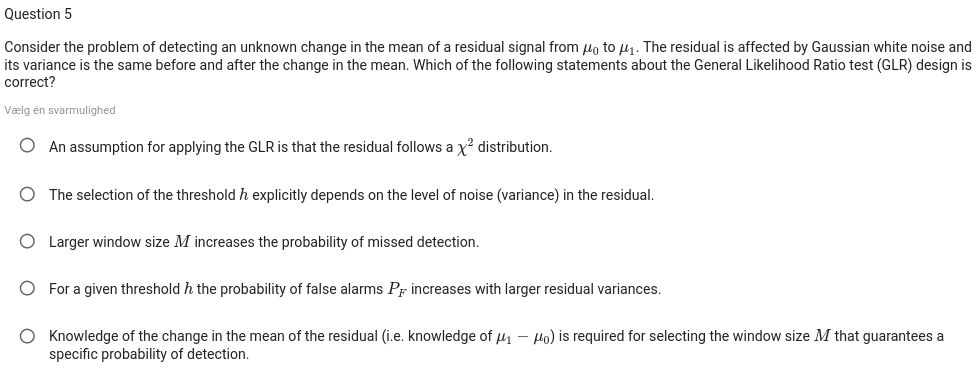

## Q6

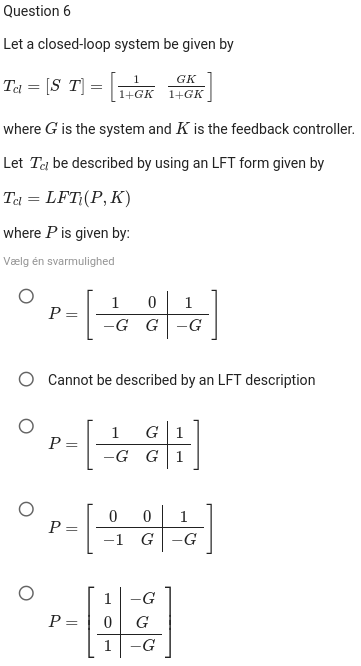

clear all;
clc;

syms G K;

% Define the correct P matrix
P = [1 0 1
    -G G -G]

$$P = \left(\begin{array}{ccc} 1 & 0 & 1\\ -G & G & -G \end{array}\right)$$

% Define the submatrices
P11 = P(1, 1:2); P21 = P(1, 3);
P12 = P(2, 1:2); P22 = P(2, 3);

% Compute the LFT: T_cl = P11 + P12*K*(I - P22*K)^(-1)*P21
T_cl = simplify(P11 + P12*K*inv(1-P22*K)*P21);

% Closed-loop transfer function Tcl = [S T]
disp(T_cl)

$$\left(\begin{array}{cc} \frac{1}{G\,K+1} & \frac{G\,K}{G\,K+1} \end{array}\right)$$

## Q7

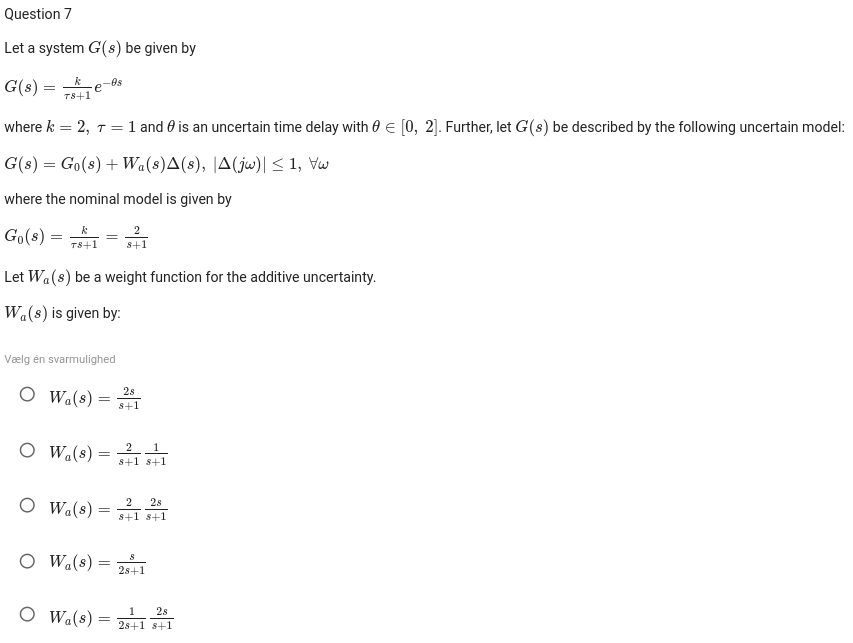

clear all; clc;

syms theta s
k = 2; tau = 1;
assume(0 <= theta & theta <=2)

G = exp(-theta*s) * k/(tau*s + 1)

$$G = \frac{2\,{\mathrm{e}}^{-s\,\theta }}{s+1}$$

G0 = k/(tau*s + 1)

$$G0 = \frac{2}{s+1}$$

Wa = G - G0

$$Wa = \frac{2\,{\mathrm{e}}^{-s\,\theta }}{s+1}-\frac{2}{s+1}$$

taylor_exp = taylor(exp(-theta*s), theta, 1);
(2*taylor_exp - 2) / (s + 1)

$$ans = -\frac{\frac{s^{3}\,{\mathrm{e}}^{-s}\,{\left(\theta -1\right)}^{3}}{3}-s^{2}\,{\mathrm{e}}^{-s}\,{\left(\theta -1\right)}^{2}-2\,{\mathrm{e}}^{-s}-\frac{s^{4}\,{\mathrm{e}}^{-s}\,{\left(\theta -1\right)}^{4}}{12}+\frac{s^{5}\,{\mathrm{e}}^{-s}\,{\left(\theta -1\right)}^{5}}{60}+2\,s\,{\mathrm{e}}^{-s}\,\left(\theta -1\right)+2}{s+1}$$

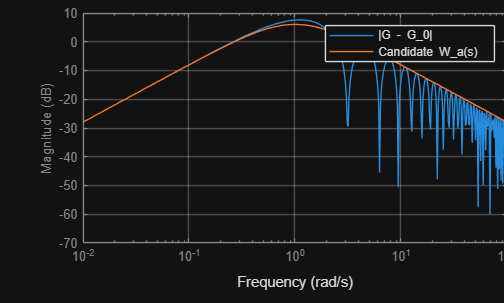


% Try all options, make the candidate W_a fit G - G0. It should align with
% the top curves
s = tf('s');

% Define the nominal model G0
G0 = 2 / (s + 1);

% Define the worst-case time delay
theta = 2;
G = G0 * exp(-theta * s);

% Define the additive uncertainty
Delta_a = G - G0;

% Frequency range for analysis
w = logspace(-2, 2, 500);
[mag, ~] = bode(Delta_a, w);
mag = squeeze(mag);

% Use 'fitmagfrd' or manual curve fitting if you have Robust Control Toolbox
% We'll define a candidate Wa(s) and compare
Wa = (2/(s + 1)) * ((2*s)/(s + 1));

% Plot to check if Wa upper-bounds Delta_a
figure;
bodemag(Delta_a, Wa, w);
legend('|G - G_0|', 'Candidate W_a(s)');
grid on; 
title('Validation of Additive Uncertainty Weight W_a(s)');

## Q8

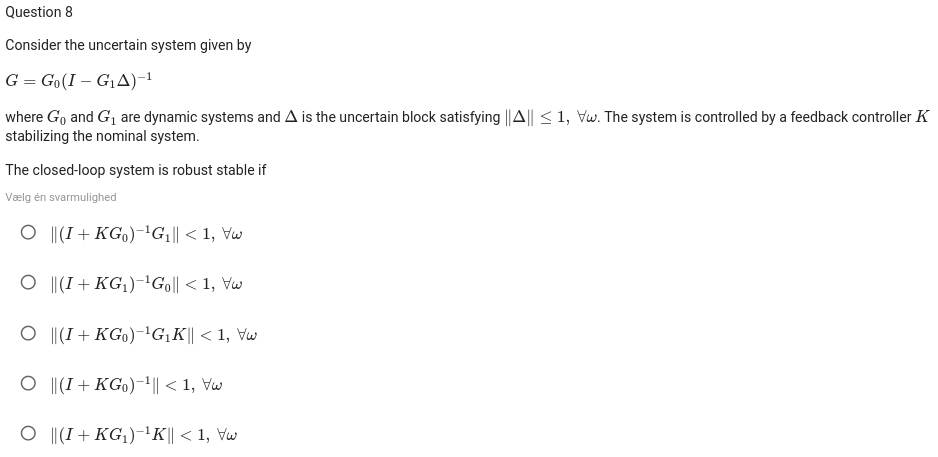

## Q9

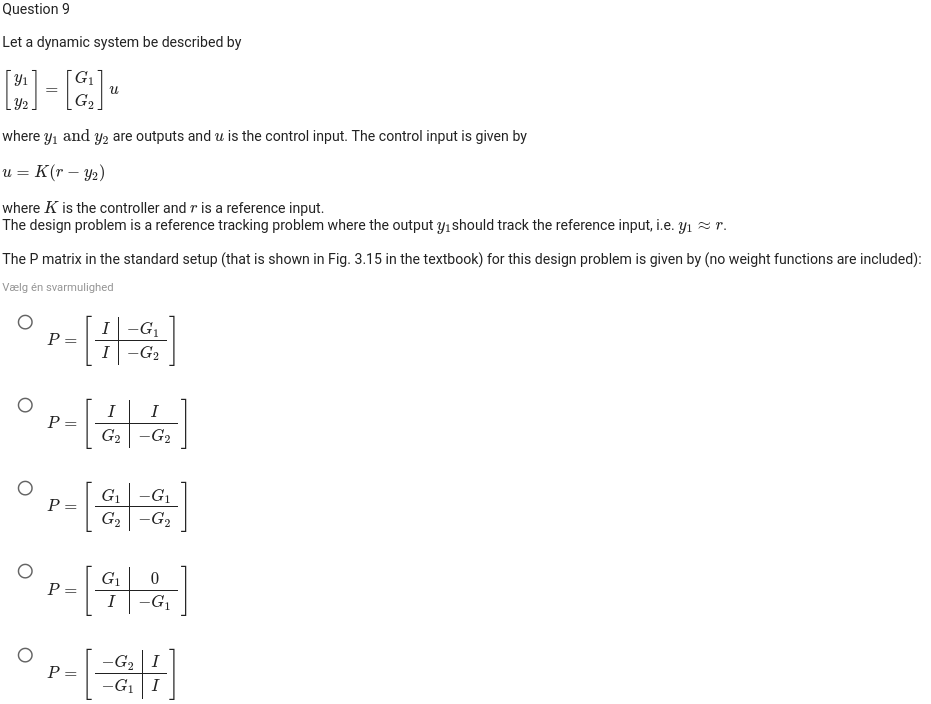

## Q10